clc;
clear;
close all;

% --- PARAMETRELER ---
M_verici = 8,  % Verici (AP) anten sayısını artırıyoruz

M_verici = 8

M_alici = 4;                    % Alıcı (Kullanıcı) anten sayısı sabit
N_qam = 4;                      % QPSK
bit_per_sym = log2(N_qam);

SNR_dB = 0:2:20;      
num_trials = 1000;              % Monte Carlo tekrar sayısı
sym_per_trial = 10000;            % Her kanalda gönderilen sembol sırası

% SONUÇLARI SAKLAMA 
BER_results_zf = zeros(length(SNR_dB),1)

BER_results_zf =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


BER_results_lmmse = zeros(length(SNR_dB),1)

BER_results_lmmse =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


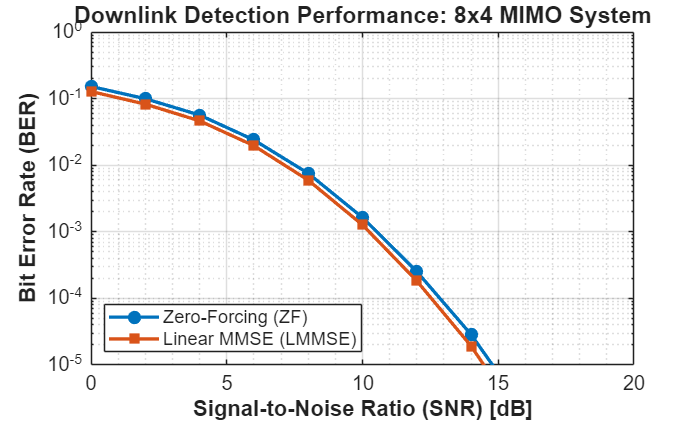



% --- SİMÜLASYON ---


for i = 1:length(SNR_dB)
    SNR_linear = 10^(SNR_dB(i) / 10);
    P_noise = 1 / SNR_linear;
    
    total_bits = 0;
    total_errors_zf=0;
    total_errors_lmmse=0;

    for j = 1:num_trials
        % 1. Veri Oluşturma (2 farklı sembol akışı)
        tx_bits = randi([0 1], M_alici * sym_per_trial * bit_per_sym, 1);
        X = qammod(tx_bits, N_qam, 'gray', 'InputType', 'bit', 'UnitAveragePower', true);
        X_parallel = reshape(X, M_alici, []); % 2 x 100 matrisi

        % 2. Kanal Oluşturma
        H = (randn(M_alici, M_verici) + 1i * randn(M_alici, M_verici)) / sqrt(2);
        
        % 3. PRECODING (ZF) - Verici Tarafı İşlemi
        % pinv(H) -> M_verici x M_alici boyutunda
        
        W_zf= pinv(H); 
        
        % Güç Normalizasyonu (Önemli: Verici gücünü sabit tutmak için)
        W_zf = W_zf / norm(W_zf, 'fro'); 
        W_lmmse = H' * inv(H * H' + P_noise * eye(M_alici));
        W_lmmse = W_lmmse / norm(W_lmmse, 'fro');

        X_precoded_zf = W_zf * X_parallel;
        X_precoded_lmmse = W_lmmse * X_parallel; % M_verici x 100 (4, 8 veya 16 antenden çıkan sinyal)

        % 4. İletim ve Gürültü
        noise = (randn(M_alici, sym_per_trial) + 1i * randn(M_alici, sym_per_trial)) * sqrt(P_noise / 2);
        Y_zf = H * X_precoded_zf + noise;
        Y_lmmse = H * X_precoded_lmmse + noise;

        % 5. Demodülasyon (Alıcıda ekstra işlem yok, çünkü ZF precoding yapıldı)
        rx_bits_zf = qamdemod(Y_zf, N_qam, 'gray', 'OutputType', 'bit', 'UnitAveragePower', true);
        
        [num_errors_zf, ~] = biterr(tx_bits, rx_bits_zf(:));
        total_errors_zf = total_errors_zf + num_errors_zf;
        total_bits = total_bits + length(tx_bits);

        rx_bits_lmmse = qamdemod(Y_lmmse, N_qam, 'gray', 'OutputType', 'bit', 'UnitAveragePower', true);
        
        [num_errors_lmmse, ~] = biterr(tx_bits, rx_bits_lmmse(:));
        total_errors_lmmse = total_errors_lmmse + num_errors_lmmse;
        


    end 
    BER_results_zf(i) = total_errors_zf / total_bits;
    BER_results_lmmse(i)=total_errors_lmmse/total_bits;

end 


% --- GÖRSELLEŞTİRME ---
% --- PROFESYONEL GRAFİK DÜZENLEME ---
figure('Color', [1 1 1]); % Beyaz arka plan
semilogy(SNR_dB, BER_results_zf, '-o', 'Color', [0 0.4470 0.7410], 'LineWidth', 2, 'MarkerSize', 6, 'MarkerFaceColor', [0 0.4470 0.7410]); 
hold on;
semilogy(SNR_dB, BER_results_lmmse, '-s', 'Color', [0.8500 0.3250 0.0980], 'LineWidth', 2, 'MarkerSize', 6, 'MarkerFaceColor', [0.8500 0.3250 0.0980]);

% Grafik Estetiği
grid on; set(gca, 'YMinorGrid', 'on', 'XMinorGrid', 'on', 'FontSize', 12);
xlabel('Signal-to-Noise Ratio (SNR) [dB]', 'FontWeight', 'bold');
ylabel('Bit Error Rate (BER)', 'FontWeight', 'bold');
title('Downlink Detection Performance: 8x4 MIMO System', 'FontSize', 14);

% Dinamik Legend
% Her çizgi için ayrı bir etiket tanımlamalısın
legend('Zero-Forcing (ZF)', 'Linear MMSE (LMMSE)','Location', 'southwest', 'FontSize', 11);
xlim([min(SNR_dB) max(SNR_dB)]);
ylim([(1e-5 - 1e-16) 1]);